%{
----- Modify Simulink to these specifications -----
PID, PI, and P feedback control
1. No coolant temperature and dilution rate step
2. No feed glucose concentration and coolant flowrate step
3. No feedforward (multicomponent switch 2)
%}

for ii = 1:1:3 % PID, PI, P
load_system("CSTR_Bioreactor_2023_FeedForward.slx");
set_param("CSTR_Bioreactor_2023_FeedForward/toggle_glucose", "Value", num2str(ii));
set_param("CSTR_Bioreactor_2023_FeedForward/toggle_biotemp", "Value", num2str(ii));
simulate = sim("CSTR_Bioreactor_2023_FeedForward");
[pv_ethanolconc, pv_biotemp, pv_ethanolconc_derivative, pv_biotemp_derivative] = extract_ts(simulate, 100, 800);
plot(pv_ethanolconc)
hold on
end

xline(150,"--")
legend("PID","PI","P","Controllers switched on","Location","Best")

xlim([125,350])

title("")
ylabel("Ethanol concentration / gL^{-1}")
xlabel("Time / h")

Plot();

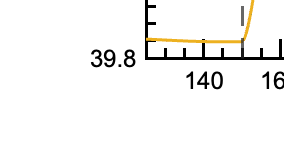

exportgraphics(gcf,"figures/FeedbackNoDisturbanceEthanol.pdf") 
hold off


%{
Need two loops for separate plots, not sure 
%}

for ii = 1:1:3 % PID, PI, P
load_system("CSTR_Bioreactor_2023_FeedForward.slx");
set_param("CSTR_Bioreactor_2023_FeedForward/toggle_glucose", "Value", num2str(ii));
set_param("CSTR_Bioreactor_2023_FeedForward/toggle_biotemp", "Value", num2str(ii));
simulate = sim("CSTR_Bioreactor_2023_FeedForward");
[pv_ethanolconc, pv_biotemp, pv_ethanolconc_derivative, pv_biotemp_derivative] = extract_ts(simulate, 100, 800);
plot(pv_biotemp)
hold on 
end

xline(150,"--")
legend("PID","PI","P","Controllers switched on","Location","Best")

ylim([31.49999, 31.500011])
xlim([150,220])

title("")
ylabel("Bioreactor temperature / °C")
xlabel("Time / h")

Plot();

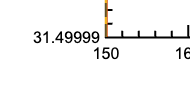

exportgraphics(gcf,"figures/FeedbackNoDisturbanceBiotemp.pdf") 
hold off